# CSMF: simultaneously learning **C**ommon and **S**pecific patterns via **M**atrix **F**actorization

- CSMF is a powerful tool to simultaneously reveals common and specific patterns from data generated under interrelated biological scenarios (e.g., cells, tissues and conditions). 

- CSMF uncovers common and specific patterns with significant biological implications in various data types such as RNA-seq, Chip-seq and scRNA-seq. 

- CSMF is a flexible non-negative matrix factorization framework, which combines data dimension reduction and differential analysis into one paradigm. 

- CSMF can infer the ranks of common patterns and specific patterns in an unsupervised manner. 

## Tutorials

In this Matlab live script (generated by Matlab R2018b), we currently provide two example workflows that outline the key steps of CSMF.

- **Simulation data:** In this simulation data, the number of samples of the first and second condition are 100 and 120, respectively. The number of features is 300. The common rank between these two data is 5, and the specific ranks are 10 and 10, respectively. 

- **ChIP-seq data of two cell lines:** This data describes the chromatin modification map on protein-DNA interactions between K562 and Huvec cell lines. This data consists of 58997 loci and 18 histone marks or TFs of K562 and Huvec cell lines.

### Key notations in this script

- X = [X1, X2, ..., Xk] is the concatenated data matrix from k conditions (Xk). 

- vecN = [n1, n2, ..., nk] defines the number of samples in each condition k (nk)

- vecPara = [rc, rs1, rs2, ..., rsk] defines the ranks of the common pattern (rc) and the k-th specific pattern (rsk).  

- The i-th common pattern is represented by C-i, and the j-th specific pattern for the k-th condition is represented by Sk-j.

If you have any problems, comments or suggestions, please contact us at Lihua Zhang (zhanglihua@amss.ac.cn) or Shihua Zhang (zsh@amss.ac.cn).

## Example I: simulation data

### Generate simulation data

Mint = 300; % the number of rows of basis matrix W
vecP = [0.2,0.2]; % a float vector with each entry equaling the probability of ...
% coefficient matrix which follows Binomial distribution for one data 
coph = 0; % an integer value controling the overlap of any column pair of ...
% basis matrix ranging from 0 to Mint
vecPara = [5,10,10]; % a vector defining the ranks of common and specific patterns
vecN = [100,120]; % an integer vector defining the number of samples of each data
tho = 0.5; % a float value defining the standard deviation of Gaussian noise
[X, W0, H0] = simulation_CSMF(Mint, vecP, coph, vecPara, vecN, tho);

### Determine the ranks of common and specific patterns

This procedure includes two steps:

- Infer the rank of each data by performing NMF and computing the stability distance.

- Decompose the inferred rank of each data into a common rank and a specific rank based on the cross-correlation between any two basis matrices of different data.

#### 1) Inference of the rank of each data

Given a predefined range of ranks [minK, maxK], we perform NMF on each data matrix.

minK = 3; maxK = 20; 
repeat = 30; % repeat >= 30
NeNMF_result = NeNMF_data(X,vecN,minK,maxK,repeat);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.


Compute the stability distance of the learned basis matrix for each rank

stability_top_record = staNMF_rank(NeNMF_result,minK,maxK,repeat);

For each data, we choose the maximum rank among the ranks corresponding to local minimum of the distance and plot the average stability distance.

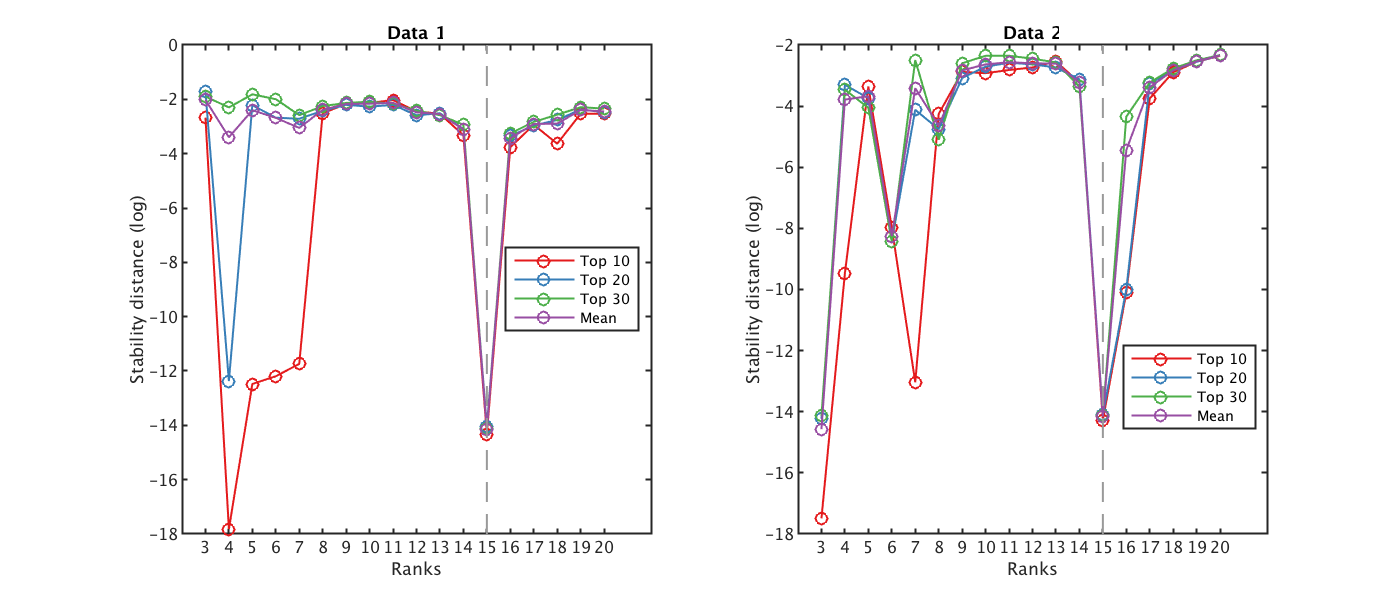

positions = find_lowrank(stability_top_record);
vecRanks = minK+positions-1; % a vector giving the inferred rank of each data
plot_stability_distance(stability_top_record,minK,maxK,positions) 

% NB: the inferred rank of each data is indicated by a grey dash line 

#### 2) Decompose the inferred rank of each data into a common rank and a specific rank

Decompose the inferred rank of each data into a common rank and a specific rank based on the cross-correlation between any two basis matrices of different data.

cutoff = 0.7;% a correlation threshold for determining the common rank
vecPara = learning_common_specific_ranks(NeNMF_result,minK,vecRanks,cutoff)

vecPara =      5    10    10


### Compute the initial values for CSMF

To improve the convergence and accuracy of CSMF, we compute the initial values using iNMF+.

repeat = 10; % run several times and select the best one
err_n = 5; % an integer value to select best performance 
[~, best_performance] = repeat_iNMF(X,vecN,vecPara,repeat,err_n); 

Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.


Winit = best_performance.W; Hinit = best_performance.H; tho = 1/size(Winit,1);

### Run CSMF with initial values from iNMF+

[~, best_performance] = repeat_CSMF(X,vecN,vecPara,repeat,...
    Winit,Hinit,tho,err_n);
best_performance

best_performance = struct with fields:
         W: [300×25 double]
         H: [25×220 double]
       err: 6.1089e+03
      iter: 40
    elapse: 14.5000


### Fine tuning the solution of CSMF  

W = best_performance.W; 
H = best_performance.H; 
inner_iter = 10; % the times of running CSMF with tunned ranks, higher than err_n
H_cutoff = 0.1; % cutoff for determing whether the row of H is common or specific
cor_cutoff = 0.7; % cutoff of correlation coefficient 
outer_iter = 50; % the outer iter of tunning CSMF algorithm
ItCSMF_record = Iterative_tunning_CSMF(X,W,H,vecN,vecPara,...
    inner_iter,err_n,H_cutoff,cor_cutoff,outer_iter);
ItCSMF_record(cellfun(@isempty,ItCSMF_record)) = [];

### Plot the basis matrix W

We concatenate the basis matrices from the common patterns (C-1, C-2, etc.) and the specific patterns in data 1 (S1-1, S1-2, etc.) and data 2 (S2-1, S2-2, etc.) into one big matrix W, and then generate the heatmap of this concatenated basis matrix. 

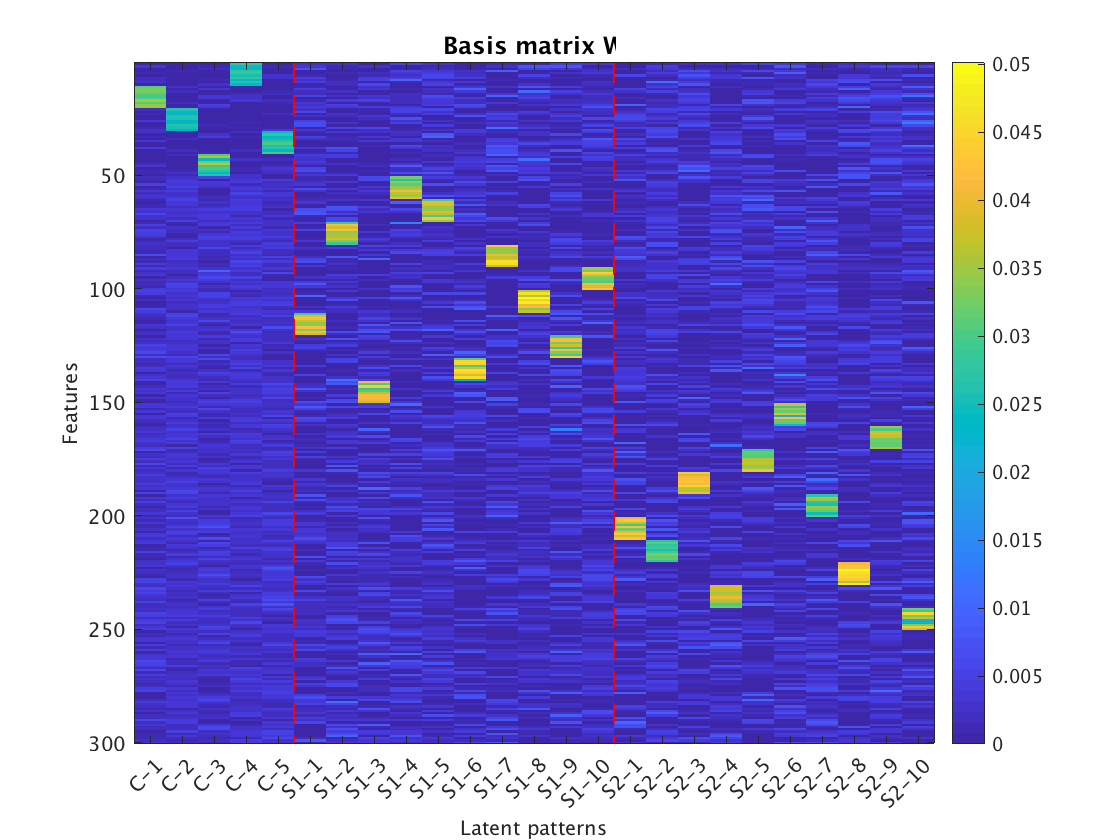

id = sum(cellfun(@length,ItCSMF_record));
W = ItCSMF_record{1,id}.W; H = ItCSMF_record{1,id}.H; 
vecPara = ItCSMF_record{1,id}.vecPara;
plot_heatmap(W,vecPara)

### Measure the accuracy of CSMF in identifying embedded patterns

[AUC,AUPR] = compute_accuracy(W,H,W0,H0)

AUC = 0.9996

AUPR = 0.9972

## Example II: Application of CSMF to ChIP-seq data between K562 and Huvec cell lines

### Load data

K562 = readtable('Ebox_K562.txt','Delimiter','\t','ReadRowNames',1);
Huvec = readtable('Ebox_Huvec.txt','Delimiter','\t','ReadRowNames',1);
X1 = table2array(K562); % rows are features (loci) and columns are samples
X2 = table2array(Huvec); % rows are features (loci) and columns are samples
X = [X1, X2]; vecN = [size(X1,2), size(X2,2)];

### Determine the ranks of common and specific patterns

This procedure includes two steps:

- Infer the rank of each data by performing NMF and computing the stability distance.

- Decompose the inferred rank of each data into a common rank and a specific rank based on the cross-correlation between any two basis matrices of different data.

#### 1) Inference of the rank of each data

Given a predefined range of ranks [minK, maxK], we perform NMF on each data matrix.

minK = 2; maxK = 6; 
repeat = 30; % repeat >= 30
NeNMF_result = NeNMF_data(X,vecN,minK,maxK,repeat);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.


Compute the stability distance of the learned basis matrix for each rank

stability_top_record = staNMF_rank(NeNMF_result,minK,maxK,repeat);

For each data, we choose the maximum rank among the ranks corresponding to local minimum of the distance and plot the average stability distance.

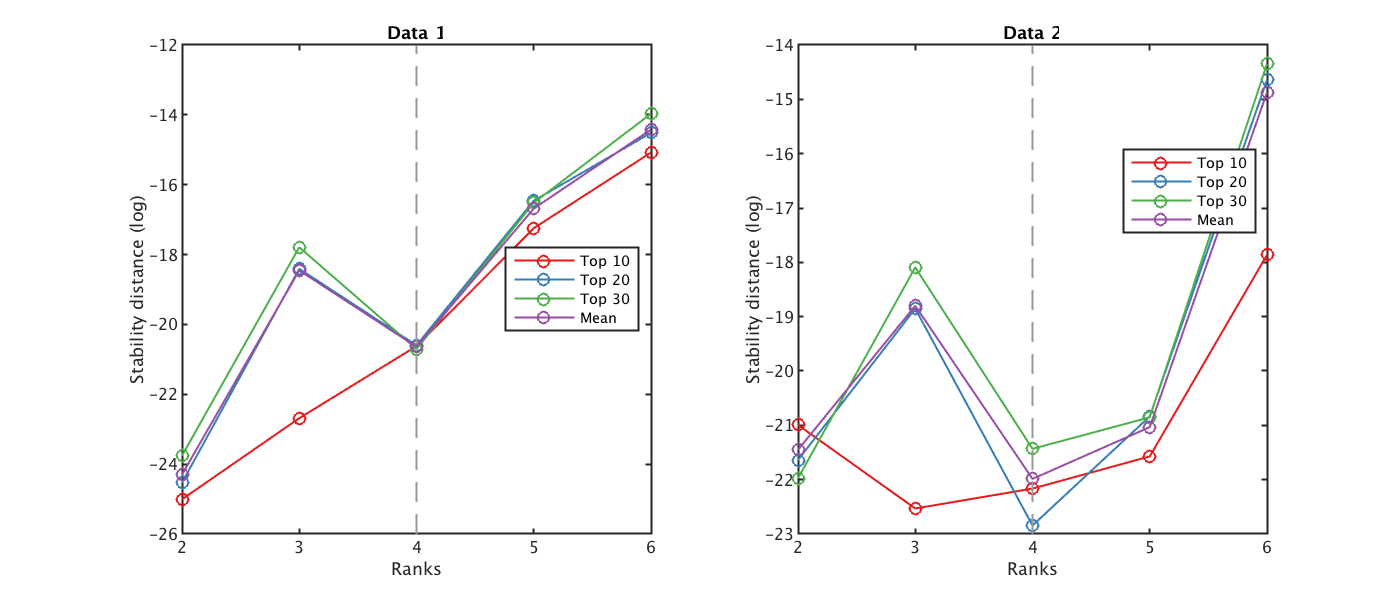

positions = find_lowrank(stability_top_record);
vecParas = minK+positions-1; % a vector giving the inferred rank of each data
plot_stability_distance(stability_top_record,minK,maxK,positions)

% NB: the inferred rank of each data is indicated by a grey dash line 

#### 2) Decompose the inferred rank of each data into a common rank and a specific rank

Decompose the inferred rank of each data into a common rank and a specific rank based on the cross-correlation between any two basis matrices of different data.

cutoff = 0.8; % a correlation threshold for determining the common rank
vecPara = learning_common_specific_ranks(NeNMF_result,minK,vecParas,cutoff)

vecPara =      1     3     3


### Compute the initial values for CSMF

To improve the convergence and accuracy of CSMF, we compute the initial values using iNMF+.

repeat = 10; % run several times and select the best one
err_n = 5; % an integer value to select best performance 
[~, best_performance] = repeat_iNMF(X,vecN,vecPara,repeat,err_n); 

Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.


Winit = best_performance.W; Hinit = best_performance.H; tho = 1/size(Winit,1);

### Run CSMF with initial values from iNMF+

[~, best_performance] = repeat_CSMF(X,vecN,vecPara,repeat,Winit,Hinit,tho,err_n);
best_performance

best_performance = struct with fields:
         W: [58997×7 double]
         H: [7×36 double]
       err: 6.1377e+05
      iter: 80
    elapse: 296.8000


### Fine tuning the solution of CSMF 

W = best_performance.W; 
H = best_performance.H; 
inner_iter = 10; % the times of running CSMF with tunned ranks, higher than err_n
H_cutoff = 0.1; % cutoff for determing whether the row of H is common or specific 
cor_cutoff = 0.8; % cutoff of correlation coefficient
outer_iter = 50; % the outer iter of tunning CSMF algorithm
ItCSMF_record = Iterative_tunning_CSMF(X,W,H,vecN,vecPara,...
    inner_iter,err_n,H_cutoff,cor_cutoff,outer_iter);
ItCSMF_record(cellfun(@isempty,ItCSMF_record)) = [];

### Plot heatmaps of the reordered concatenated basis matrix W and the concatenated coefficient matrix H

We concatenate the basis matrices from the common patterns (C-1, C-2, etc.) and the specific patterns in data 1 (S1-1, S1-2, etc.) and data 2 (S2-1, S2-2, etc.) into one big matrix W, and then generate the heatmap of this concatenated basis matrix. 

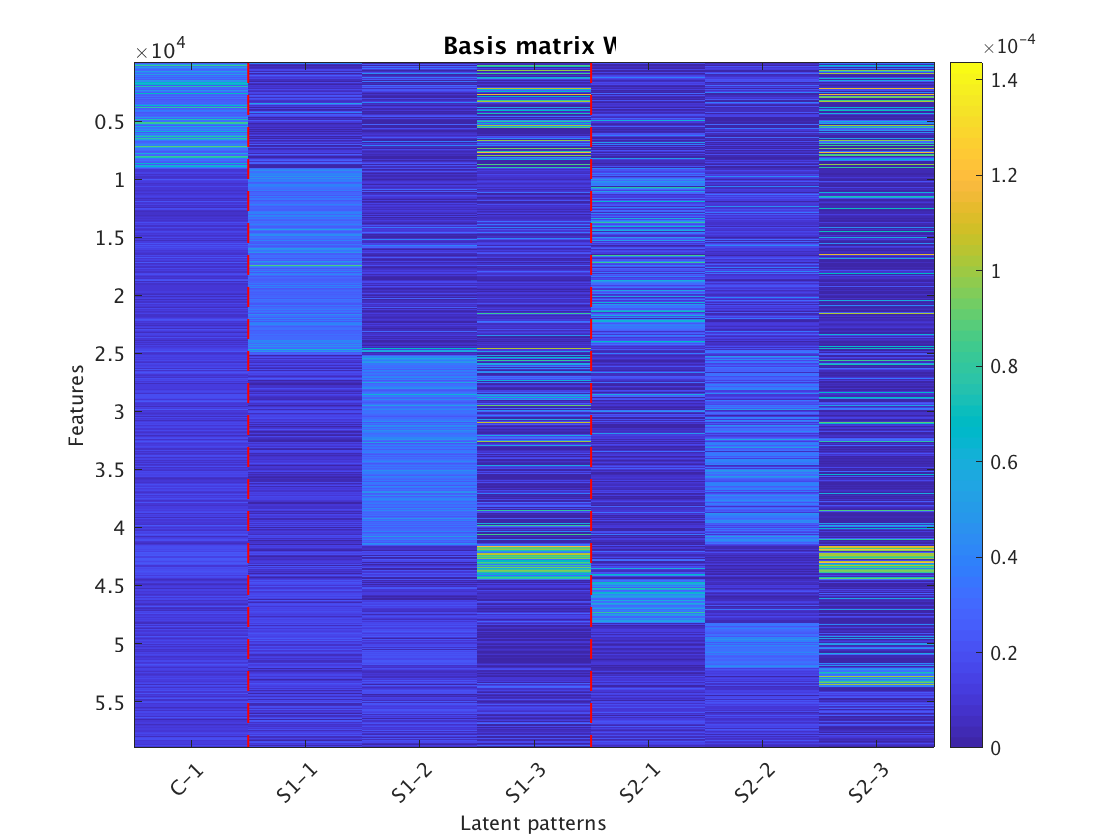

id = sum(cellfun(@length,ItCSMF_record));
W = ItCSMF_record{1,id}.W; H = ItCSMF_record{1,id}.H; vecPara = ItCSMF_record{1,id}.vecPara;
cutoff1 = 0.5; % the z-score cutoff of W
cutoff2 = 0.5; % the z-score cutoff of H
[X_orid,W_orid,H_orid,~,~] = reorder_zscore(W,H,cutoff1,cutoff2,vecN,vecPara);
plot_heatmap(W_orid,vecPara)

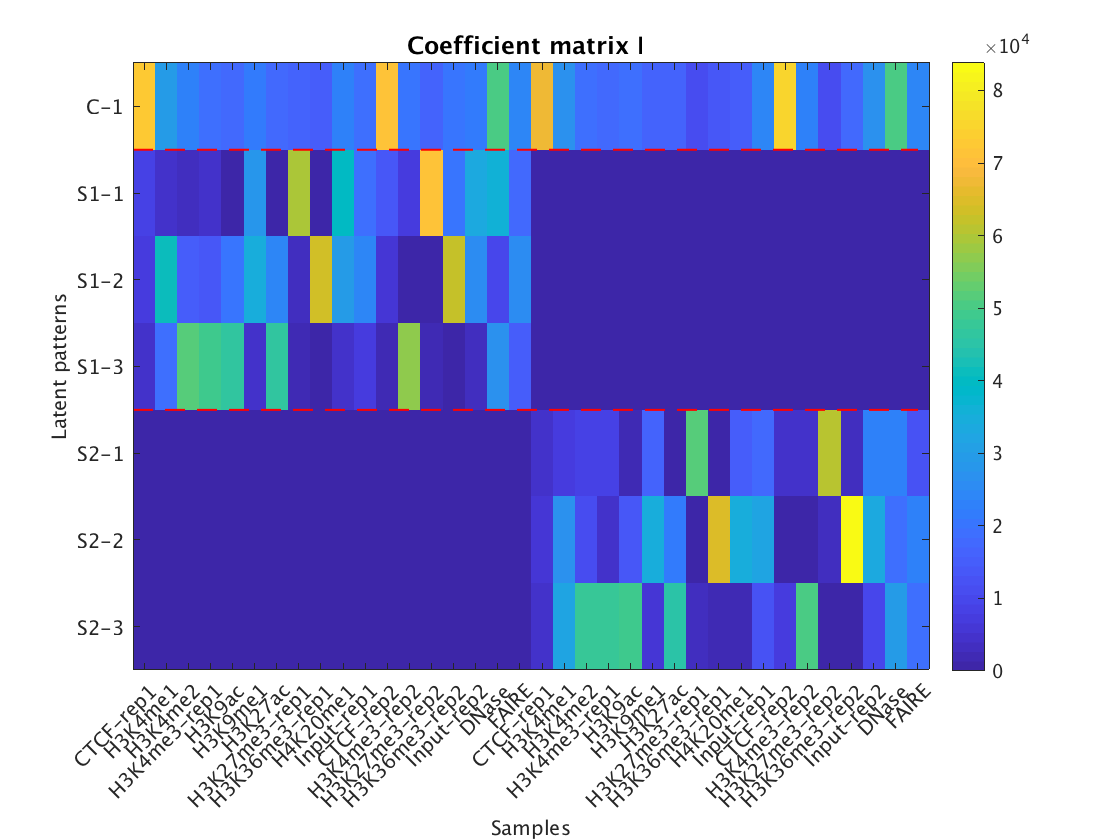

plot_heatmap(H',vecPara,'Transp','T','Samplename',Huvec.Properties.VariableNames)